clear
n = 25;
mu = 0.01

mu = 0.0100

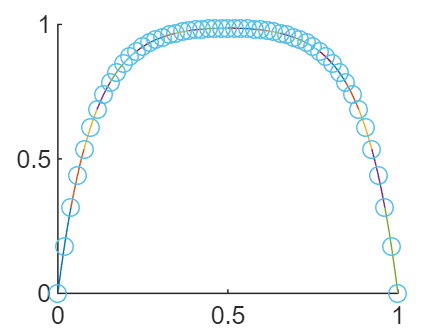

addpath('../');
[u, fu, dfu] = fem_p2(n, mu);

figure
xx = linspace(0, 1, 2*n + 3);
h = 1/(n+1);
hold on
for j = 1:2:2*n+1
    a = xx(j);
    b = xx(j+2);
    f = fu{(j+1)/2};
    xcurr = linspace(a, b, 10)';
    ucurr = f(xcurr);
    plot(xcurr, ucurr)
end
scatter(xx, u_true(xx, mu))
hold off